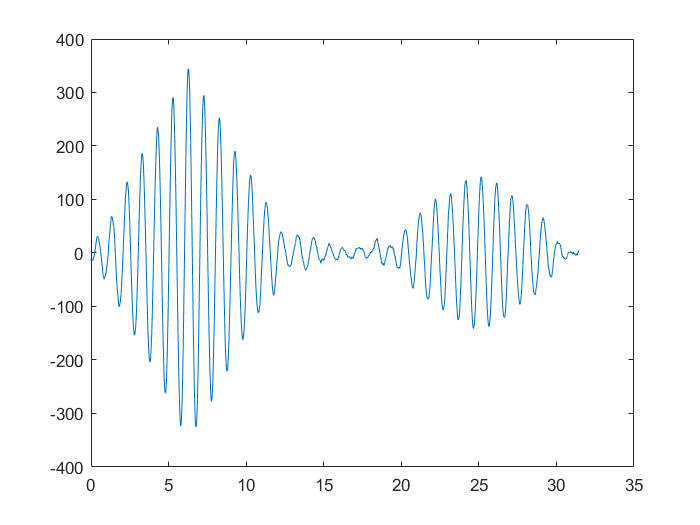


  t = 0 : 0.01 : 2*pi;
            f = 1;
            w = 2 * pi * f;
            L = length(t);
            A = 1;
            attenuation = 0.5;    
            SD = 1;
     
                    y1 = A*sin(w*t);
                    y2 = attenuation*A*sin(w*t);
                   
                    
                    r = [zeros(1,L), y1, zeros(1,2*L), y2, zeros(1,L) ];
                    r = r+ randn(1,length(r))*SD;
                    ct1 = length(r)-L;
                    
                    for a = 0:ct1
                        c(a+1) = r(a+1:a+L)*y1';
                    end
         
          [m,k1] = max(c);
          c2 = c(length(t)*2 : end);
          [n,k2] = max(c2);
          tl = ((k2+length(t)*2)-k1)*0.01;
          D = tl/2*3*100000000;
          
          
          
          plot((0:length(c)-1)*0.01, c)